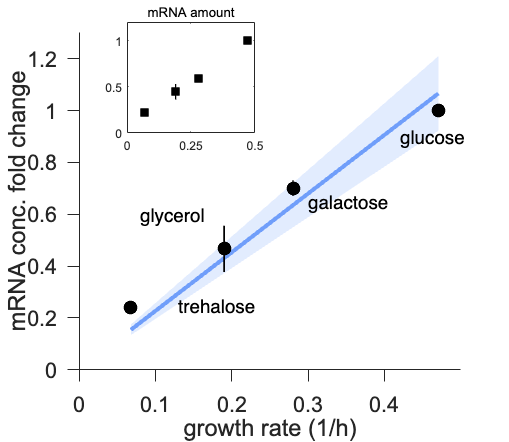

%% ========================================================================
%  mRNA–ribosome growth model — mass-action framework
%  Purpose:
%    Using measured mRNA and ribosome concentrations, this model applies a
%    mass-action steady-state formulation to compute the active ribosome
%    fraction (translation-competent pool).  
%
%    Assuming the peptide elongation rate is conserved across conditions,
%    the resulting active ribosome fraction allows direct inference of
%    cellular growth rate as a function of mRNA and ribosome concentrations.
%
%  Assumes:
%    - color_rgb.mat on path (defines color_rb, rgb_sort, etc.)
%    - growth&ribo data.mat on path (growth rate, ribosome fractions)
%    - lfst_ss_x.m on path (steady-state solution function)
%    - adjust_fig_nogrid.m on path (figure styling utility)
% ========================================================================

clear all; clc;
global km ar br gamma glu_ba_ratio

%% ------------------------------ Setup ------------------------------------
load("color_rgb.mat");
color_n = [0.6 0.6 0.6];  % marker color for nitrogen conditions

gamma        = 24;    % binding model parameter
glu_ba_ratio = 3.1;   % glucose baseline ratio (used later)
cp           = 9;     % growth scaling constant

% Carbon sources (fixed order)
condition_four = {'Glucose','Galactose','Glycerol','Trehalose'};

%% ------------------------------ Data -------------------------------------
load('growth&ribo data.mat');   % provides: growth_rate, active_ribo_40s, ribo_pro_frac, etc.

% Collect row indices of the four carbon conditions in order
indices = [];
for i = 1:length(condition_four)
    temp_indices = find(strcmp(condition, condition_four{i}));
    indices = [indices; temp_indices];
end

% Active ribosome (% -> [0,1]), growth, volume, ribosome proteome fraction
active_ribo        = active_ribo_40s;
growth_rate_key_m  = nanmean(growth_rate(indices,:), 2);   % (4x1) growth rate
active_ribo_key_m  = nanmean(active_ribo(indices,:)')/100; % fraction
active_ribo_key_sem= nanstd(active_ribo(indices,:)', 0, 1) ./ sqrt(2) / 100;

volume     = [53.3133 44.9267 50.7800 48.2433];
volume_SEM = [0.5682 1.5354 0.9404 0.8722];

phi_ribo_four     = nanmean(ribo_pro_frac(indices,:), 2)';  % (1x4)
phi_ribo_four_SEM = nanstd(ribo_pro_frac(indices,:), 0, 2) ./ sqrt(sum(~isnan(ribo_pro_frac(indices,:)), 2));
phi_ribo_four_SEM = phi_ribo_four_SEM';

% mRNA (main panel plots concentration; inset plots amount)
fit_type = 'linear'; % 'linear' or 'hill'
mRNA_concentration     = [1 0.7006 0.4663 0.2394];
mRNA_concentration_sem = [0.0135 0.0300 0.0892 0.0159];

mRNA_amount     = [1.0000 0.5904 0.4442 0.2167];
mRNA_amount_sem = [0.0082 0.0153 0.0845 0.0138];

%% ----------------- Fit mRNA concentration vs growth (0–0.5 h^-1) ----------
maskFit = (growth_rate_key_m >= 0) & (growth_rate_key_m <= 0.5);
x_all   = growth_rate_key_m(:);
y_all   = mRNA_concentration(:);

xData = x_all(maskFit);
yData = y_all(maskFit);

% Choose model and robust StartPoint
if strcmp(fit_type,'linear')
    ft   = fittype('km*x', 'independent','x','dependent','y');
    opts = fitoptions('Method','NonlinearLeastSquares','Display','Off','StartPoint', 0.3);
elseif strcmp(fit_type,'hill')
    % y = km*x/(x + dm)
    ft   = fittype('km*x./(x + dm)', 'independent','x','dependent','y');
    opts = fitoptions('Method','NonlinearLeastSquares','Display','Off','StartPoint', [0.3 0.1]);
else
    error('fit_type must be ''linear'' or ''hill''.');
end

[fitresult, gof] = fit(xData, yData, ft, opts); %#ok<ASGLU>
km = fitresult.km;
if strcmp(fit_type,'hill'); dm = fitresult.dm; end %#ok<NASGU>

%% ------------------ Plot: fit + 90% CI + SEM (concentration) --------------
figure; hold on;

% Predict and CI over sorted x for a clean band
[xFit, sortIdx] = sort(xData); %#ok<ASGLU>
yFit = feval(fitresult, xFit);

ci_level = 0.90;
yCI  = predint(fitresult, xFit, ci_level, 'functional','on');
ci_low = yCI(:,1); ci_hi = yCI(:,2);

% CI band
hFill = fill([xFit; flipud(xFit)], [ci_low; flipud(ci_hi)], rgbTriplet(3,:), 'LineStyle','none');
set(hFill, 'FaceAlpha', 0.2);

% Fit curve
plot(xFit, yFit, 'LineWidth', 3, 'Color', rgbTriplet(3,:));

% Raw points + SEM
errorbar(x_all, y_all, mRNA_concentration_sem, 'LineStyle','none', 'Marker','o', 'MarkerSize',9, ...
    'MarkerFaceColor','k','MarkerEdgeColor','k', 'CapSize',0,'Color','k','LineWidth',1.2);

% Optional equation label
if strcmp(fit_type,'linear')
    eqnStr = sprintf('y = %.2f x', km); %#ok<NASGU>
else
    eqnStr = sprintf('y = %.2f x/(x + %.2f)', km, dm); %#ok<NASGU>
end
% Example: text(0.02, 1.2, eqnStr, 'Units','normalized');

% Axis and labels
xlim([0 0.5]); ylim([0 1.3]);
text(0.42, 0.90, 'glucose',   'FontSize',14);
text(0.30, 0.65, 'galactose', 'FontSize',14);
text(0.08, 0.60, 'glycerol',  'FontSize',14);
text(0.13, 0.25, 'trehalose', 'FontSize',14);
xlabel('growth rate (1/h)');
ylabel('mRNA conc. fold change','Interpreter','none');
adjust_fig_nogrid; legend off;
set(gcf,'Position',[100 100 380 330]);

%% ------------------------- Inset: mRNA amount -----------------------------
axInset = axes('Position',[0.25 0.7 0.25 0.25]); % [left bottom width height]
box on; hold(axInset,'on');
errorbar(axInset, x_all, mRNA_amount, mRNA_amount_sem, ...
    'LineStyle','none', 'Marker','s', 'MarkerSize',7, ...
    'MarkerFaceColor','k','MarkerEdgeColor','k', 'CapSize',0,'Color','k','LineWidth',1.0);
xlim(axInset,[0 0.5]); ylim(axInset,[0 1.2]);
title(axInset,'mRNA amount','FontSize',10);
set(axInset,'XTick',[0 0.25 0.5],'YTick',[0 0.5 1.0]);


%% ---------------- Ribosome proteome fraction vs growth (linear) ----------
load('growth&ribo data.mat'); % (kept as in original)
figure
[xData, yData] = prepareCurveData( mean(growth_rate,2), nanmean(ribo_pro_frac,2)); % assume ribo conc. is 1/5 of mRNA in glucose

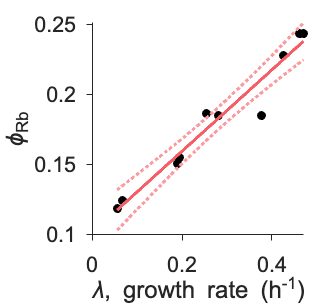

ft   = fittype( 'ar*x+br', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares', 'Display', 'Off', ...
                   'StartPoint', [0.311215042044805 0.162182308193243] );

[fitresult, gof] = fit( xData, yData, ft, opts ); %#ok<ASGLU>
ar=fitresult.ar; br=fitresult.br;
h = plot( fitresult, xData, yData,'predfunc',0.95);
h(1,1).MarkerFaceColor=[0 0 0];
h(1,1).MarkerSize=20; h(1,1).MarkerEdgeColor=[0 0 0];
h(2).LineWidth=2.5;  h(2).Color=rgbTriplet(11,:);
h(3).LineWidth=2.5;  h(3).Color=sqrt(rgbTriplet(11,:));
h(4).LineWidth=2.5;  h(4).Color=sqrt(rgbTriplet(11,:));
xlabel('\lambda, growth rate (h^{-1})');
ylabel('\phi_{Rb}');
adjust_fig_nogrid; legend off;
set(gcf,'position',[100 100 250 230])

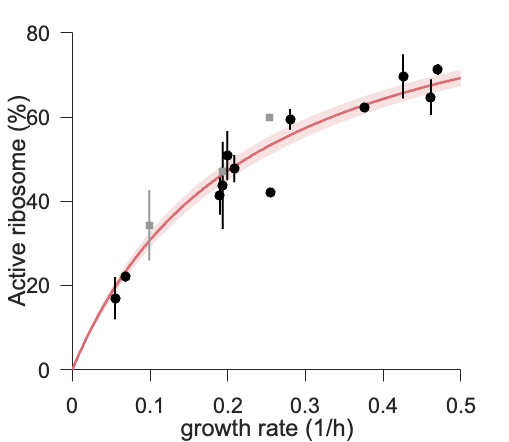


%% --------------------- predict inactive ribo fraction ---------------------
% -------------------------------------------------------------------------
% Fit alpha_0 via coarse search + fitnlm; then plot fit with 90% CI
% -------------------------------------------------------------------------

%% 1) Data (SMT carbon 12; nitrogen 3)
xData       = nanmean(growth_rate,2);
yData       = nanmean(active_ribo, 2);
yErr        = range(active_ribo, 2) / 2;

xNitrogen    = nanmean(nitrogen_gr,2);
yNitrogen    = nanmean(nitrogen_active_ribo, 2);
yErrNitrogen = range(nitrogen_active_ribo, 2) / 2;

% combine for fitting
x_all = [xData; xNitrogen];
y_all = [yData; yNitrogen];

%% 2) Coarse search alpha_0 (skip if known)
alpha_0_list = 1 : 0.01 : 5;
lfst = zeros(size(alpha_0_list));
for i = 1:numel(alpha_0_list)
    for k = 1:numel(x_all)
        % lfst_ss_x returns fraction (0–1); convert to %
        pred = lfst_ss_x(alpha_0_list(i), x_all(k), fit_type);
        lfst(i) = lfst(i) + (pred - y_all(k)/100).^2;
    end
end
[~, idx] = min(lfst);
alpha_0 = alpha_0_list(idx);

%% 3) Nonlinear fit (fitnlm, parameter b(1)=alpha_0)
tbl = table(x_all, y_all, 'VariableNames', {'x','y'});
nlm = fitnlm( tbl, @(b, x)(100 * lfst_ss_x(b(1), x, fit_type)), alpha_0 );

%% 4) Predict curve + 90% CI
x_pred = linspace(0, 0.5, 200)';  
[ ypred, CI ] = predict(nlm, x_pred, 'Alpha', 0.10, 'Prediction','curve' );

%% 5) Plot
figure; hold on;
fill( [x_pred; flipud(x_pred)], [CI(:,1); flipud(CI(:,2))], color_rb(1,:), ...
      'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', '90% CI' );
plot( x_pred, ypred, 'LineWidth', 2, 'Color', color_rb(1,:), 'DisplayName','Model fit' );
errorbar( xData,     yData,     yErr,        'o','MarkerFaceColor','k','Color','k','LineWidth',1.5, 'DisplayName','SMT data','CapSize',0);
errorbar( xNitrogen, yNitrogen, yErrNitrogen,'s','MarkerFaceColor',color_n,'Color',color_n,'LineWidth',1.5, 'DisplayName','Nitrogen-limited','CapSize',0);
axis([0 0.5 0 80]);
xlabel('growth rate (1/h)'); ylabel('Active ribosome (%)');
legend('Location','best'); adjust_fig_nogrid;

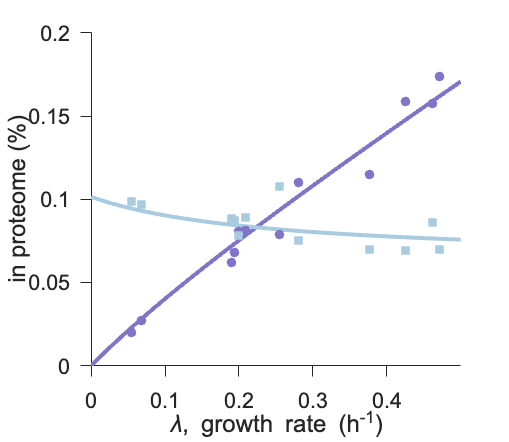

set(gcf, 'Position', [100 100 380 330]);

lambda_list = [0:0.01:0.5];
figure; hold on;
plot(lambda_list, (ar*lambda_list+br).* lfst_ss_x(alpha_0, lambda_list, fit_type), ...
    'LineWidth', 3, 'Color', rgb_sort(1,:), 'DisplayName', 'active ribosome content');
plot(lambda_list, (ar*lambda_list+br).*(1- lfst_ss_x(alpha_0, lambda_list, fit_type)), ...
    'LineWidth', 3, 'Color', rgb_sort(3,:), 'DisplayName', 'inactive ribosome content');
scatter(nanmean(growth_rate,2),nanmean(ribo_pro_frac,2).*mean(active_ribo,2)/100,50,rgb_sort(1,:),"filled");
scatter(nanmean(growth_rate,2),nanmean(ribo_pro_frac,2).*(1-mean(active_ribo,2)/100),70,rgb_sort(3,:),"filled",'s');
adjust_fig_nogrid; set(gcf, 'position', [100 100 380 330]); 
axis([0 0.5 0 0.2]);
ylabel('in proteome (%)'); xlabel('\lambda, growth rate (h^{-1})');

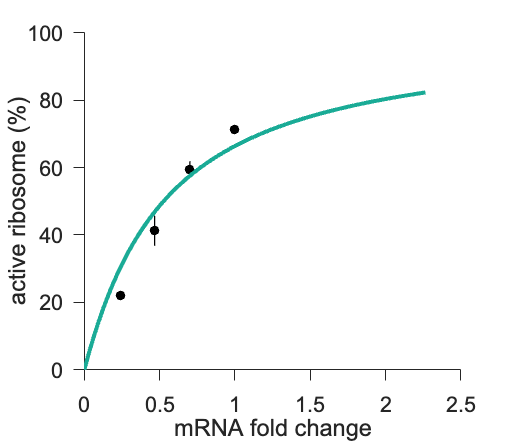


lambda_list = [0:0.01:1];

protein_0 = alpha_0*glu_ba_ratio/ribo_pro_frac(5); % baseline total ribosome capacity

figure; hold on;
errorbar(mRNA_concentration, 100*active_ribo_key_m, 100*active_ribo_key_sem, ...
    'o', 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k', 'Color', 'k', 'CapSize', 0, ...
     'LineWidth', 1);

if strcmp(fit_type,'linear')
    x_1 = ribo_ratio_ss((km*lambda_list)*alpha_0, 0.25*protein_0, gamma);
    plot((km*lambda_list), 100*x_1, 'LineWidth',3,'Color',rgbTriplet(4,:));
elseif strcmp(fit_type,'hill')
    x_1 = ribo_ratio_ss(km*lambda_list./(lambda_list+dm)*alpha_0, (ar*lambda_list+br)*protein_0, gamma);
    plot(km*lambda_list./(lambda_list+dm), 100*x_1, 'LineWidth',3,'Color',rgbTriplet(4,:));
end
xlabel('mRNA fold change'); ylabel('active ribosome (%)');
legend('Model results','SMT data'); adjust_fig_nogrid;

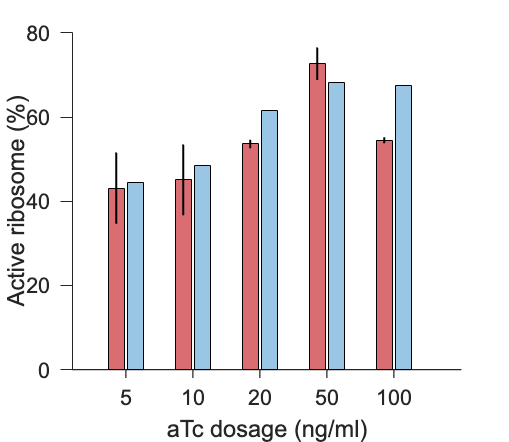

set(gcf,'position',[100 100 380 330])

%% ------------------------------- aTc -------------------------------------
% aTc dosage vs mRNA and active ribosome (compare SMT vs model)
figure; hold on;

alpha0_scale = 0:0.01:1.4; %#ok<NASGU>
atc_gr    = [0.243, 0.241, 0.268, 0.318, 0.303];
atc_mRNA  = [0.410798559, 0.479134236, 0.80005073, 1.063233009, 1.026980438]';

% SMT replicates (%)
atc_active_ribo = { ...
    [35.3, 34, 60], ...
    [39.8, 33.9, 61.5], ...
    [52.6, 54.6], ...
    [76.5, 68.8], ...
    [53.8, 55.2] ...
};

% Model predictions (%)
for i = 1:5
    predict_active_ribo(i,1) = ribo_ratio_ss(atc_mRNA(i)*alpha_0, (ar*atc_gr(i)+br)*protein_0, gamma);
end
mean_atcribo = cellfun(@mean, atc_active_ribo);
sem_atcribo  = cellfun(@(x) std(x)/sqrt(length(x)), atc_active_ribo);
err_neg = sem_atcribo; err_pos = sem_atcribo;

bar_data = [mean_atcribo', predict_active_ribo * 100];
b = bar(bar_data, 'grouped', 'BarWidth', 0.85);
b(1).FaceColor = color_rb(1, :);  % SMT
b(2).FaceColor = color_rb(2, :);  % Prediction
drawnow;

x_exp = b(1).XEndPoints;
y_exp = bar_data(:,1);
errorbar(x_exp, y_exp, err_neg, err_pos, 'k', 'LineStyle','none', 'LineWidth',1.5, 'CapSize',0);
set(gca, 'XTick', 1:5, 'XTickLabel', {'5','10','20','50','100'}, 'FontSize', 12);
xlabel('aTc dosage (ng/ml)'); ylabel('Active ribosome (%)');
legend({'SMT data','Predictions'}, 'Location','best');
adjust_fig_nogrid; hold off;
axis([0.2 6 0 80]);

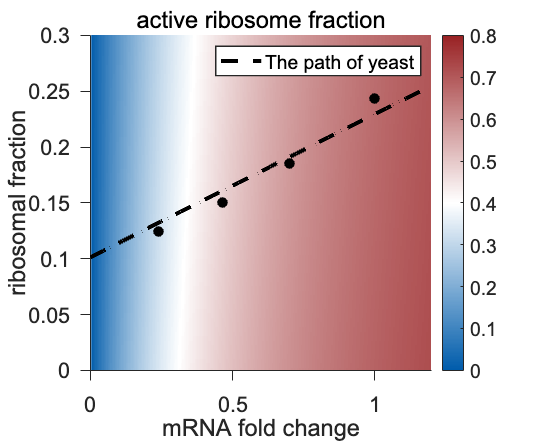

set(gcf,'Position',[100,100,380,330]);

%% --------------------- (Optional) schematic diagram ----------------------
% (kept commented as in your original)
% figure; hold on;
% gr_sd = linspace(0, 0.5, 100);
% if strcmp(fit_type,'linear'); yFit = km * gr_sd;
% else;                         yFit = km * gr_sd ./ (gr_sd + dm); end
% plot(gr_sd, yFit*alpha_0,'LineWidth',6,'Color',rgbTriplet(3,:));
% plot(gr_sd,(ar*gr_sd+br)*protein_0,'LineWidth',6,'Color',rgbTriplet(11,:));
% plot(gr_sd,10*lfst_ss_x(alpha_0,gr_sd,fit_type),'LineWidth',6,'Color',rgbTriplet(4,:));
% plot(gr_sd,mRNA_capacity,'LineWidth',6,'Color',rgbTriplet(9,:));
% adjust_fig_nogrid;

%% --------------------- Phase maps (alpha–beta scans) ---------------------
% Minimal changes; identical logic with added comments
alpha_range = 0.01:0.01:3;
beta_range  = 0.01:0.1:10;

x_low = zeros(length(beta_range), length(alpha_range));
active_ribo_conc = zeros(length(beta_range), length(alpha_range));
growth_rate_predict = zeros(length(beta_range), length(alpha_range));

for i = 1:length(alpha_range)
    for j = 1:length(beta_range)
        alpha = alpha_range(i);
        beta  = beta_range(j);
        x_1   = ribo_ratio_ss(alpha,beta,gamma);
        x_low(j,i)            = x_1;
        active_ribo_conc(j,i) = x_1*beta;
        growth_rate_predict(j,i) = cp*x_1*(beta/protein_0)/(11984/3600);
    end
end

% Heatmap: active ribosome fraction
figure; hold on;
imagesc(alpha_range/alpha_0, beta_range/protein_0, x_low);
if strcmp(fit_type,'linear')
    plot(km*lambda_list,(ar*lambda_list+br),'--','LineWidth',3,'Color',[0 0 0]);
elseif strcmp(fit_type,'hill')
    plot(km*lambda_list./(lambda_list+dm),(ar*lambda_list+br),'LineWidth',4,'Color',[1 1 1]);
end
scatter(mRNA_concentration,phi_ribo_four,60,'black','filled');
colorbar; xlabel('mRNA fold change'); ylabel('ribosomal fraction');
set(gca, 'YDir', 'normal');
axis([0 1.2 0 0.3]); adjust_fig_nogrid;
title('active ribosome fraction'); legend('The path of yeast')
colormap(redwhiteblue(256)); caxis([0 0.8]);
set(gcf,'position',[100 100 400 330])

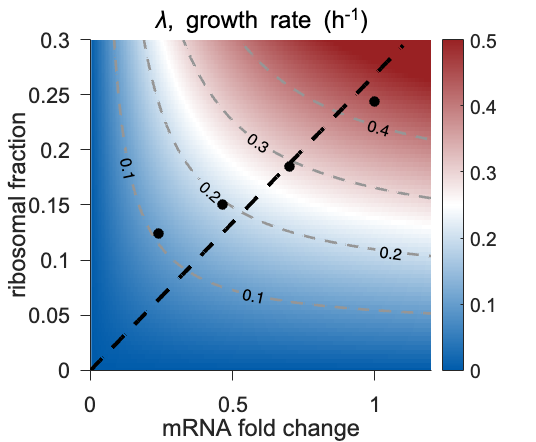


% Heatmap: growth rate with iso-contours
figure; hold on;
imagesc(alpha_range/alpha_0, beta_range/protein_0, growth_rate_predict);
[C, h] = contour(alpha_range/alpha_0, beta_range/protein_0, growth_rate_predict, [0.1 0.2 0.3 0.4], '--', ...
    'LineColor', [150 150 150]/255, 'LineWidth', 2);
clabel(C, h, 'FontSize', 12, 'Color', 'k');
h1 = scatter(mRNA_concentration, phi_ribo_four, 60, 'black', 'filled'); %#ok<NASGU>

% Force-through-origin linear fit y = k*x for visual guide
k = sum(mRNA_concentration .* phi_ribo_four) / sum(mRNA_concentration .^ 2);
x_fit = linspace(0, max(mRNA_concentration)*1.1, 100);
y_fit = k * x_fit;
h2 = plot(x_fit, y_fit, 'k--', 'LineWidth', 3); %#ok<NASGU>

xlabel('mRNA fold change'); ylabel('ribosomal fraction');
axis([0 1.2 0 0.3]); adjust_fig_nogrid; title('\lambda, growth rate (h^{-1})');
colormap('redwhiteblue'); colorbar; legend off; caxis([0 0.5]);
set(gcf,'position',[100 100 400 330])

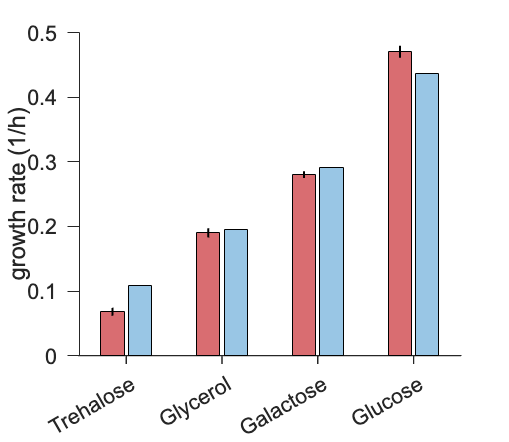


%% --------------- Predicted vs measured growth (four carbons) -------------
figure;
growth_rate_four_pre = [];
for ii=1:4
    alpha = mRNA_concentration(ii)*alpha_0;
    beta  = phi_ribo_four(ii)*protein_0;
    x_1   = ribo_ratio_ss(alpha,beta,gamma);
    x_low(ii)            = x_1; %#ok<AGROW>
    active_ribo_conc(ii) = x_1*beta; %#ok<AGROW>
    growth_rate_four_pre(ii) = cp*x_1*(beta/protein_0)/(11984/3600);
end

growth_rate_true = growth_rate([5 4 6 12],:);

% Mean ± SEM across replicates
gr_true_mean = mean(growth_rate_true, 2);
gr_true_sem  = std(growth_rate_true, 0, 2) ./ sqrt(size(growth_rate_true, 2));

% Grouped bars: Measured vs Predicted; reorder as in the caption
bar_data = [gr_true_mean, growth_rate_four_pre(:)];
reorder_idx = [4, 3, 2, 1];
bar_data = bar_data(reorder_idx, :);
gr_true_sem = gr_true_sem(reorder_idx);

% Compute x-positions for error bars
ngroups = size(bar_data, 1);
nbars   = size(bar_data, 2);
groupwidth = min(0.8, nbars/(nbars + 1.5));
x = nan(ngroups, nbars);
for i = 1:nbars
    x(:,i) = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
end

% Plot grouped bars + SEM on measured bars
figure; hold on;
b = bar(bar_data, 'grouped', 'BarWidth', 0.85);
b(1).FaceColor = color_rb(1, :);   % measured
b(2).FaceColor = color_rb(2, :);   % predicted
errorbar(x(:,1), bar_data(:,1), gr_true_sem, 'k', 'LineStyle','none', 'LineWidth',1.5, 'CapSize',0);
ylabel('growth rate (1/h)');
xticks(1:4);
xticklabels({'Trehalose','Glycerol','Galactose','Glucose'});
legend({'Measured', 'Predicted'}, 'Location', 'northeast');
adjust_fig_nogrid; set(gcf,'position',[100 100 380 330])


%% --------------------------- Local function -------------------------------

function active_ratio = ribo_ratio_ss(a,b,g)
%RIBO_RATIO_SS Steady-state active ribosome ratio for a minimal binding model.
% Model (dimensionless):
%   dx/dt = a*(1-x)*(1-y) - x
%   dy/dt = g*(1-x)*(1-y) - b*y
% We use the low-occupancy branch closed form. Returns active ratio x+y.
    y_low = (a+b+g+a.*g - sqrt((a+b+g+a.*g).^2 - 4*a.*(b+b.*g))) ./ (2*b + 2*b.*g);
    x_low = y_low .* g;
    active_ratio = x_low + y_low;  % fraction in [0,1]
end
